生成仿真用的数据

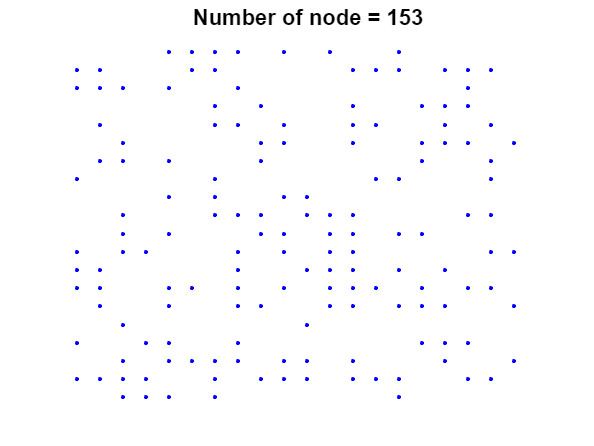

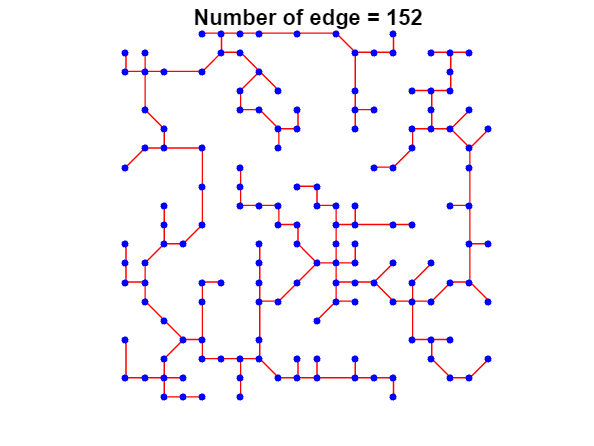

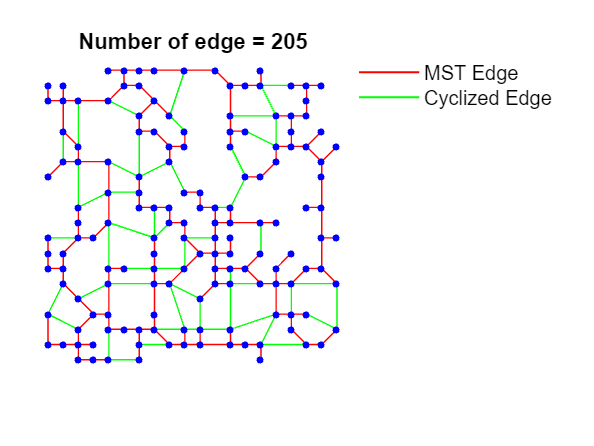

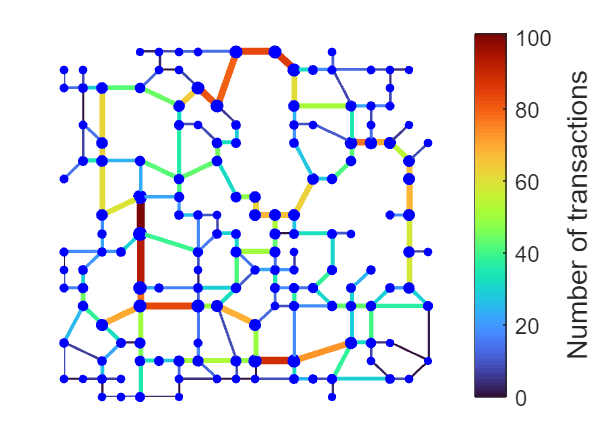

[dataGenArgs] = dataGen();

执行外部解题程序，并读入程序的输出

system("..\build\x64-Release\main.exe");

newEdge.size = 94 
Total Cost = 94351844 


[totCost, edgeStat, sortedEdgeStat, edgePile, transactionPassEdgeID, transactionMinPath] = readResult();

对结果进行可视化分析

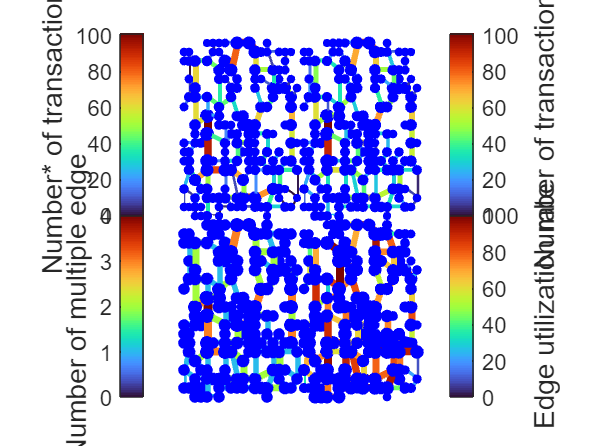

[TransactionAllocation] = plotOverview(edgeStat);

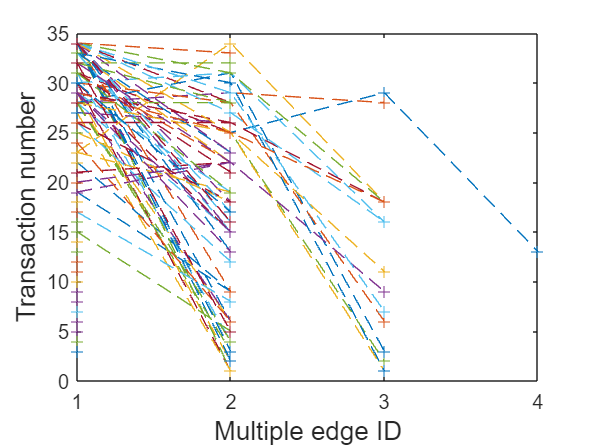

[TranNumInMiltiEdge] = plotTranNumInMultiEdge(edgeStat);

transactionID = 140;
edgePassed1 = transactionMinPath{transactionID};
[UsedPile1] = plotUsedPile(edgePile, edgePassed1);

edgePassed2 = transactionPassEdgeID{transactionID};
[UsedPile2] = plotUsedPile(edgePile, edgePassed2);

[singleBusinsee] = plotSingleTransaction(edgeStat, edgePile, edgePassed1, edgePassed2);